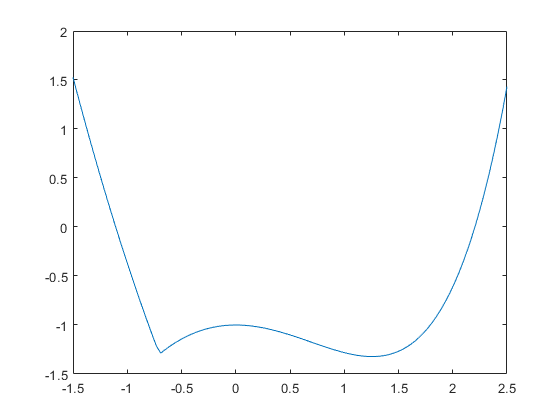

f=@(x) abs(exp(x) - x.^2) - x - 2;
xx = linspace(-1.5,2.5,100);

xx_l = linspace(-1.5,-1,10);
xx_r = linspace(2,2.5,10);

yy_l = f(xx_l);
yy_r = f(xx_r);


plot(xx,f(xx))


plot(xx_l,yy_l,"r*")
hold on
plot(xx_r,yy_r,"r*")
P_l = polyfit(xx_l, yy_l, 9)

P_l =    -0.0000   -0.0000   -0.0002   -0.0013   -0.0083   -0.0416   -0.1666    0.5000   -2.0000   -3.0000


P_r = polyfit(xx_r, yy_r, 9)

P_r =     0.0000   -0.0003    0.0024   -0.0082    0.0358   -0.0121    0.2380   -0.5616    0.0314   -1.0072


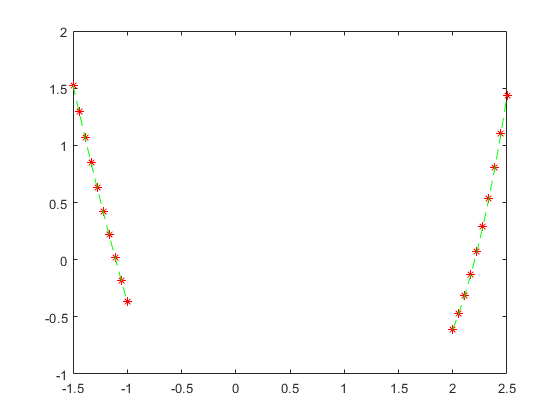

plot(xx_l,polyval(P_l,xx_l),"g--")
plot(xx_r,polyval(P_r,xx_r),"g--")

hold off

%Inverse interpolation find roots
P_l = polyfit(yy_l, xx_l, 9)

P_l =     0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0003   -0.0021    0.0188   -0.2822   -1.1065


P_r = polyfit(yy_r, xx_r, 9)

P_r =     0.0004   -0.0018    0.0034   -0.0048    0.0078   -0.0146    0.0298   -0.0724    0.2737    2.2041


plot(xx,f(xx))
hold on
root_l = polyval(P_l,0)

root_l = -1.1065

root_r = polyval(P_r,0)

root_r = 2.2041

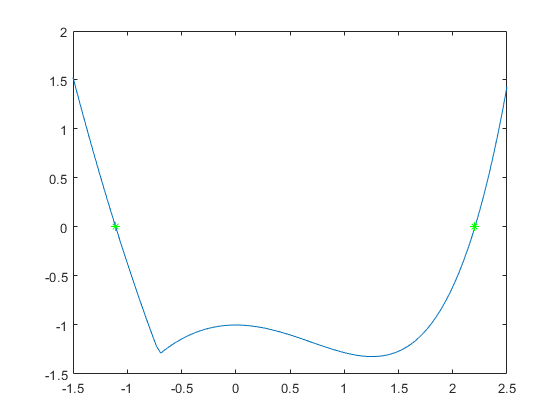

plot(root_l,0,"g*")
plot(root_r,0,"g*")

hold off